# Hands-On -  White Noise WSS Stochastic Process: Estimation of the Correlation Function and the Spectral Power Density from Data

## Introduction

Given a stationary (in weak sense) white noise stochastic process


$$$v(\cdot) \sim WN(0,\lambda^2)$$$


with mean value $\text{E}\left[v(t)\right]=0$ and variance $\sigma^2_{v} = \lambda^2$, it is well known that the **autocorrelation function** is 


$$\gamma(\tau)=
\left \{
\begin{array}{ll}
\lambda^2 , \quad & \tau =0 \\
0 , & \tau \not= 0
\end{array}
\right .$$


and the corresponding **spectral power density** 


$$\Gamma(\omega) = 
\sum_{\tau=-\infty}^{+\infty} 
\gamma(\tau) e^{-j \omega \tau} \, = \, \lambda^2\, , \quad
\forall \, \omega \in [-\pi,\pi]$$


where


$$\gamma(0) = \frac{1}{2\pi} \int_{-\pi}^{\pi}
\Gamma(\omega) d \omega = \frac{1}{2\pi}\lambda^2 \times 2\pi =
\lambda^2$$


### A Practical Issue

Suppose we now acquire a finite number $N$ of samples from a WSS stationary white noise process. How can we estimate the autocorrelation function and spectrum from the available data?

## Sampled Estimator of the Mean Value, the Variance and the Autocorrelation Function

We have already analysed the sampled estimators of mean value and variance. We recall them for convenience.

### Sample Average Estimator 

Given $N$ random variables $\, v(1)\,,\; v(2)\,,\; \ldots\,,\; v(N) \,$such that


$$\text{E} \left[ v(i) \right] = \mu_v\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  v(i) - \mu_v \right] \, \left[ v(j) - \mu_v \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\mu}_{v} = \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} v(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\mu_{v}}\right] = \mu_{v}$$


### The Sample Variance

The sample variance of $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with known mean $\mu_v$ is defined as 


$$ \hat \sigma^2_{\mu_v,N}={\frac {1}{N}}\sum _{i=1}^{N}(v_{i}-\mu_v)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. 

In practice, **the mean value is often unknown** and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(v_{i}-\hat \mu_N)^2$$


### The Sample Autocorrelation Function

Given $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with **null mean value** $\mu_v = \text{E}\left[ v_i \right] = 0 \; \forall i$, the autocorrelation function $\gamma_{v}(\tau)$ can be estimated by mean of the following expression


$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le N-1$$


It can be proven that it is an **unbiased estimator **(refer to [1] for details). Moreover, it can be proven that the variance of the estimate converges to zero as $N \to \infty$, so the estimate $\hat{\gamma}(\tau)$ is a **consistent estimate** of $\gamma(\tau)$ (refer to [1] for details).

## Hands On: Estimated Autocorrelation Function and Spectrum for a WSS Stationary White Noise Stochastic Process

Let us generate $N$ samples of a WSS stationary white noise stochastic process, with zero mean and variance $\lambda^2$.

Collect the data and then apply the sampled estimators.

clear variables
close all
clc

### First Example: a Gaussian White Noise Stochastic Process

Ndata = 23000;   % select how many samples to collect and store

varWG = 3.5; % select the white noise variance

WGsamples = sqrt(varWG)*randn(Ndata,1); % let's generate the white noise samples

Let's estimate the mean value and the variance

av_val = mean(WGsamples)      % the average value

av_val = -0.0116


sampled_var = var(WGsamples)  % the sampled variance

sampled_var = 3.5420

Run more than once, varying the variance of the process. Observe the convergence of the sampled estimates of the mean vakue and the variance to the effective values, when increasing the number of collected data.

**What about the autocorrelation function?**

Ncorr = 1000; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

Have a look to the command input and output variables, and to some application examples, using 

[gamma_v, lags_v] = xcorr(WGsamples, Ncorr,'unbiased'); 
% unbiased estimation of the autocorr. function

Now let's plot 

- the acquired samples of the white noise

- the samples of the estimated autocorrelation function

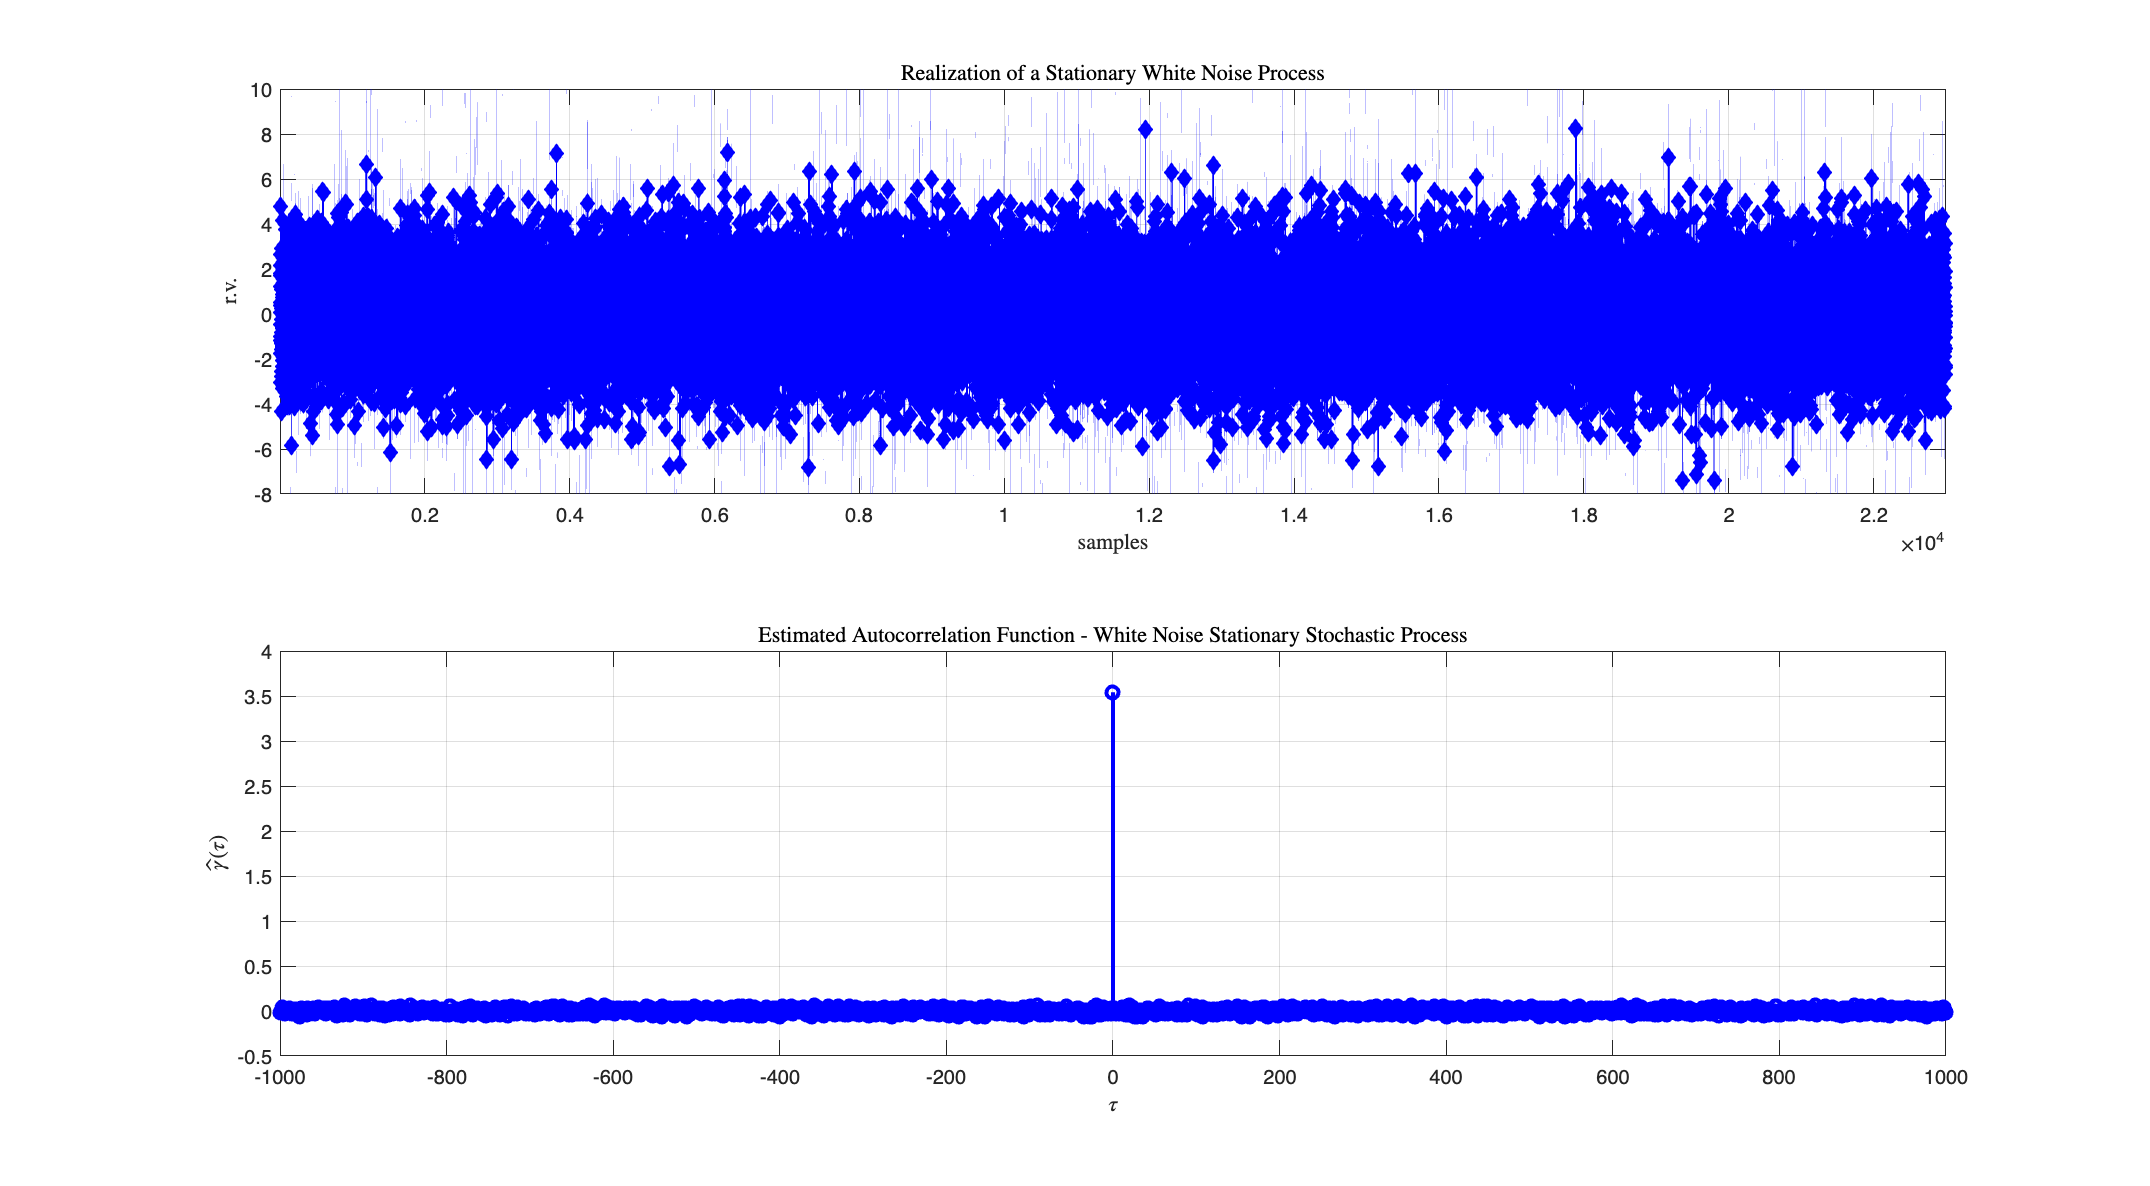

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);
plot(WGsamples,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary White Noise Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis

subplot(2,1,2);
stem(lags_v, gamma_v,'b', 'LineWidth',2);grid on;
xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - White Noise Stationary Stochastic Process',...
    'Interpreter','latex');

### Estimation of the Spectral Power Density from Data 

So far, we estimated the average value, the variance of the r.v. of the process and the autocorrelation function, just using the collected data. What about the **spectrum**?

Given the samples of the estimated autocorrelation function $\hat{\gamma}(\tau)$, the **estimate of the spectrum** can be evaluate  according to the so-called ***"periodogram"***** algorithm**

### Spectral Power Density Estimation: the Periodogram 

Given $2N-1$ samples of the autocorrelation function $\hat{\gamma}(\tau)\,,\quad \tau = -N+1\,,\; -N+2\,,\; \ldots\, N-2\,,\; N-1$, where $N$is the number of collected samples of the r.v.

- the Fourier transform of the autocorrelation function estimate is

$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$    (++)

- by substituting into $\hat{\Gamma}(\omega)$ the expression of $\hat{\gamma}(\tau)$ as function of the samples $v(n)$, and taking into account the properties of the autocorrelation function (the correlation function is an even function), the estimate $\hat{\Gamma}(\omega)$ can also be expressed as

$\hat{\Gamma}(\omega) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} \right\vert^{2} = \displaystyle \frac{1}{N}  \left\vert \hat{V}(\omega) \right\vert^{2} $  where $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $    (*)

- It can be proven  that the expected value of the estimated spectrum is a **smoothed version of the true spectrum**. Moreover, it suffers from the same **spectral leakage problems** which are due to the finite number of data points (refer to [1] for details). Hence **the periodogram is not a consistent estimate** of the true power density spectrum.

- Over the years, many other methods have been proposed, with the aim of obtaining a consistent estimate of the power spectrum, but these algorithms are outside the scope of this live script (and these topics are not included in the course). For details, please refer to a textbook on "Digital Signal Processing" such as [1].

#### The Algorithm: Using the DFT in Power Spectrum Estimation

- given $N$ samples of the r.v. $v$, evaluate $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $, using the DFT algorithm, or more efficiently the FFT algorithm;


$$\hat{\Gamma}\left( 2\pi \displaystyle \frac{k}{N} \right) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\,2 \pi \,n\,\frac{k}{N}} \right\vert^{2} \qquad k = 0\,,\;1\,,\;2\,,\;\ldots N-1$$


#### The Algorithm: Practical Implementation

Given the samples, collected in the `array WGsamples`, let's apply the "periodogram" algorithm to estimate the spectrum:

- Evaluate the DFT of the data sequence

WG_FFTd = fft(WGsamples);   % compute the FFT of the data sequence

WG_FFT = fftshift(WG_FFTd); % rearrange the array of the FFT, by shifting 
                           % the zero-frequency component to the 
                           % center of the array.

- Compute the power spectrum estimate according to Eq. (*)

powerSpectrum = (abs(WG_FFT).^2)/Ndata; 
% squared magnitude, scaled by the number of samples Nstep
% and scaled also by the 


- Compute the corresponding angular frequencies

omegaPSD = linspace(-pi,pi,Ndata); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum


- plotting the spectrum

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD,powerSpectrum, 'LineStyle','-','LineWidth',2); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');

#### **Remark**

As written above, the periodogram is an estimate that can be very rough: this is the case. Anyway, if we evaluate the average spectral power density:

% the average spectral power density
averagePSD = mean(powerSpectrum)

averagePSD = 3.5420

As can be seen, the value obtained is close enough to the variance of white noise

varWG

varWG = 3.5000

All'aumentare del numero di dati, la forma dello spettro non migliora. C'e` un principio di indeterminazione: se ho un buon risultato nel tempo ce l'ho brutto nella frequenza e viceversa. 

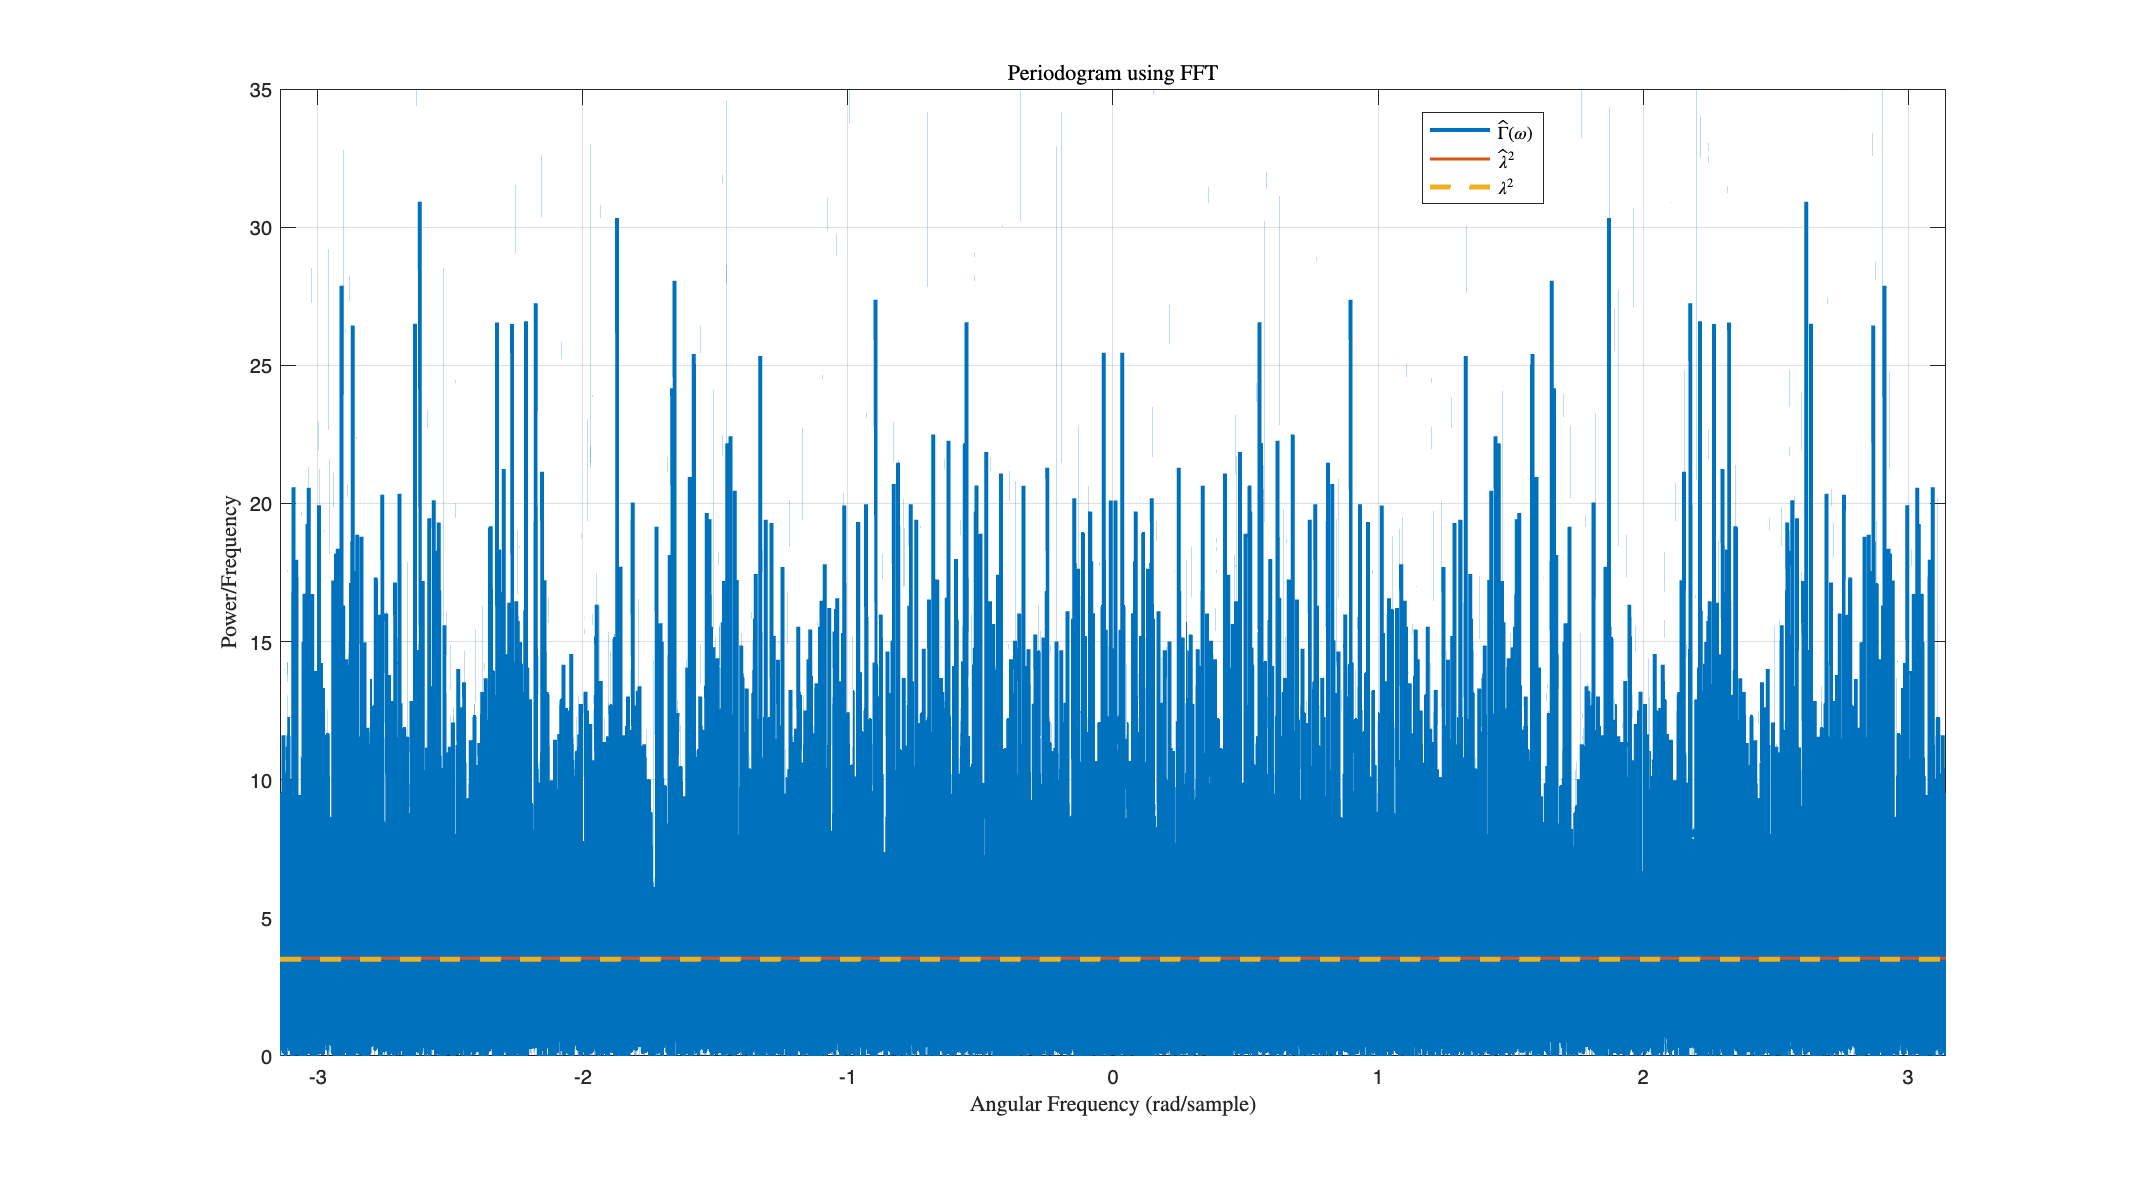



hold on;
omExtrema = [-pi, +pi]; % the min & max angular frequency
plot(omExtrema, [averagePSD, averagePSD], 'LineStyle','-', 'LineWidth',1.5);
% a stright line - the average power density

plot(omExtrema, [varWG, varWG], 'LineStyle','--', 'LineWidth',2.5); 
% a stright line - the effective power density

legend('$\hat{\Gamma}(\omega)$','$\hat{\lambda}^{2}$', '$\lambda^2$',...
    'Location','best', 'Interpreter', 'latex');

### Spectrum Estimation: a Different Approach

Let's apply directly Eq. (++)

$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$    (++)

where

### 
$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le M \ll N-1
$$


Ncorr_b = 48; % estimate M values of the autocorrelation function -- M << N-1

[gamma_vB, lags_vB] = xcorr(WGsamples, Ncorr_b,'unbiased'); 
% unbiased estimation of the autocorr. function
WG_FFT_B = fftshift(fft(gamma_vB));   % compute the FFT of the data sequence
% rearrange the array of the FFT, by shifting the zero-frequency component to the 
% center of the array.

powerSpectrumB = abs(WG_FFT_B); 
% according to Eq. (++)

omegaPSD_B = linspace(-pi,pi,numel(gamma_vB)); 
% (2 pi)/numel(gamma_vB) is the angular frequency resolution for the spectrum


- plotting the spectrum

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD_B,powerSpectrumB, 'LineStyle','-','LineWidth',2); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');
% the average spectral power density
averagePSD_B = mean(powerSpectrumB)

averagePSD_B = 3.5420

As can be seen, the value obtained is close enough to the variance of white noise

varWG

varWG = 3.5000

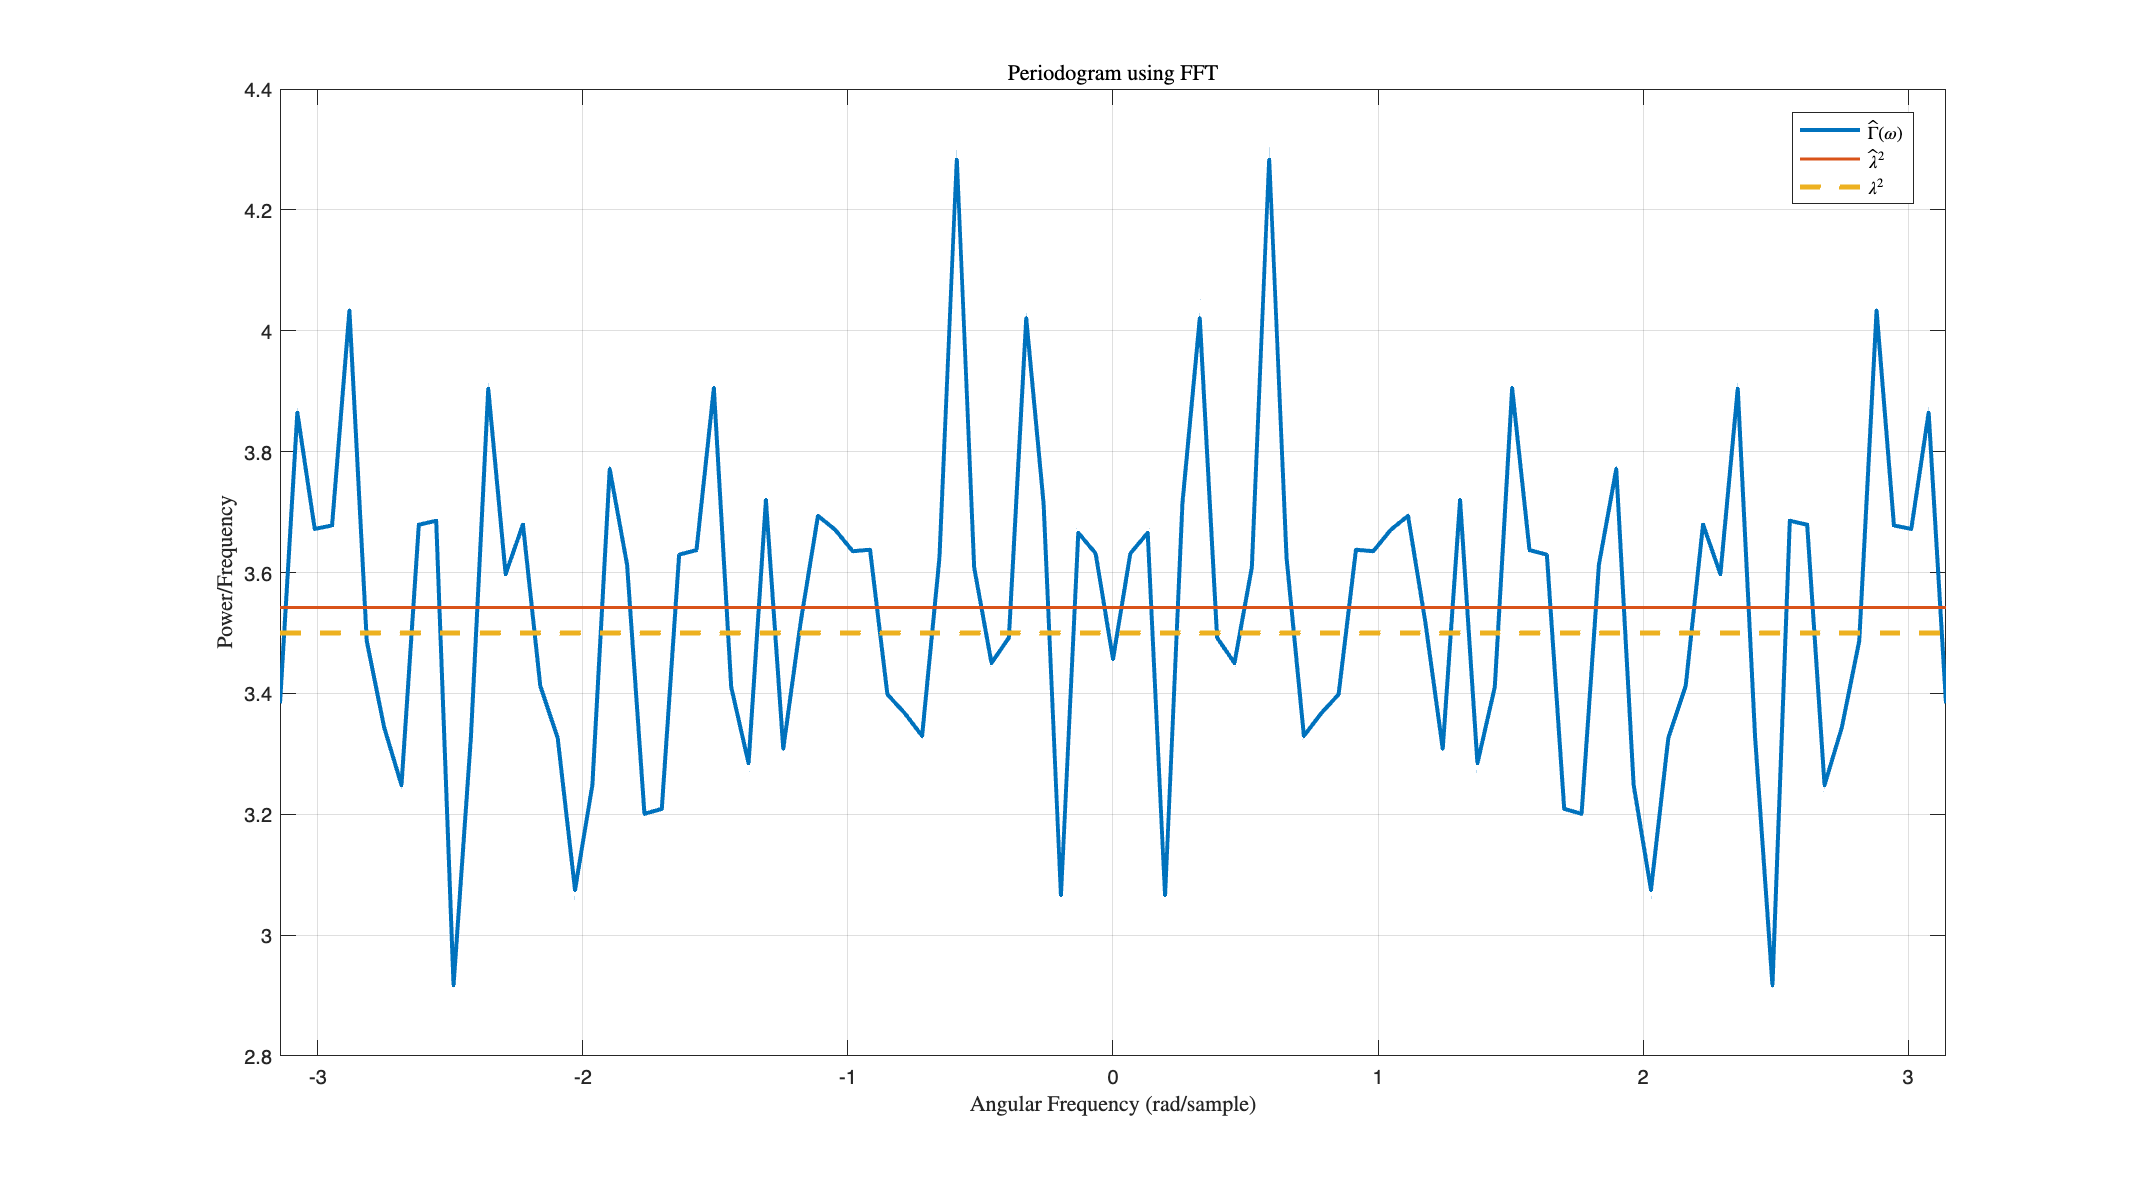



hold on;
omExtrema = [-pi, +pi]; % the min & max angular frequency
plot(omExtrema, [averagePSD_B, averagePSD_B], 'LineStyle','-', 'LineWidth',1.5);
% a stright line - the average power density

plot(omExtrema, [varWG, varWG], 'LineStyle','--', 'LineWidth',2.5); 
% a stright line - the effective power density

legend('$\hat{\Gamma}(\omega)$','$\hat{\lambda}^{2}$', '$\lambda^2$',...
    'Location','best', 'Interpreter', 'latex');

### Second Example: a Uniform Distributed White Noise Stochastic Process

Let us consider a stationary white noise process $v(n)$, with as probability density function the uniform probability density in the interval $[-1\,,\;+1]$


$$f_{v}(q) = \left\{ \begin{array}{lcl}
0.5 &\quad & -1 \le q \le +1\\
0 &\quad & q \notin \left[-1\,,\;+1\right]
\end{array} \right.$$


Verify that


$$\text{E}[v(n)] =0 \qquad \text{var}\left(v(n)\right) = \displaystyle \frac{1}{3}$$


**Hint**: consider a r.v. $x$ uniformly distrbuted in the interval $[0\,,\;+1]$ and apply the linear transformation $y = a+(b-a)\cdot x$, with $a\,,\;b \in \mathbb{R}$. Evaluate $\text{E}[y]$ and $\text{var}(y)$.

Ndata = 49000;   % select how many samples to collect and store

varWU = 1/3; % the white noise variance

WUsamples = -1+2*rand(Ndata,1); % let's generate the white noise samples 
                                % using the linear transformation of a 
                                % uniformly distributed r.v. in [0, 1] to
                                % the desired r.v. uniformly distributed
                                % in [-1, +1]

Let's estimate the mean value and the variance

av_val = mean(WUsamples)      % the average value

av_val = -2.1065e-04


sampled_var = var(WUsamples)  % the sampled variance

sampled_var = 0.3338

Run more than once, varying the variance of the process. Observe the convergence of the sampled estimates of the mean vakue and the variance to the effective values, when increasing the number of collected data.

**What about the autocorrelation function?**

Ncorr = 240; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

Have a look to the command input and output variables, and to some application examples, using 

[gamma_vU, lags_v] = xcorr(WUsamples, Ncorr,'unbiased'); 
% unbiased estimation of the autocorr. function

Now let's plot 

- the acquired samples of the white noise

- the samples of the estimated autocorrelation function

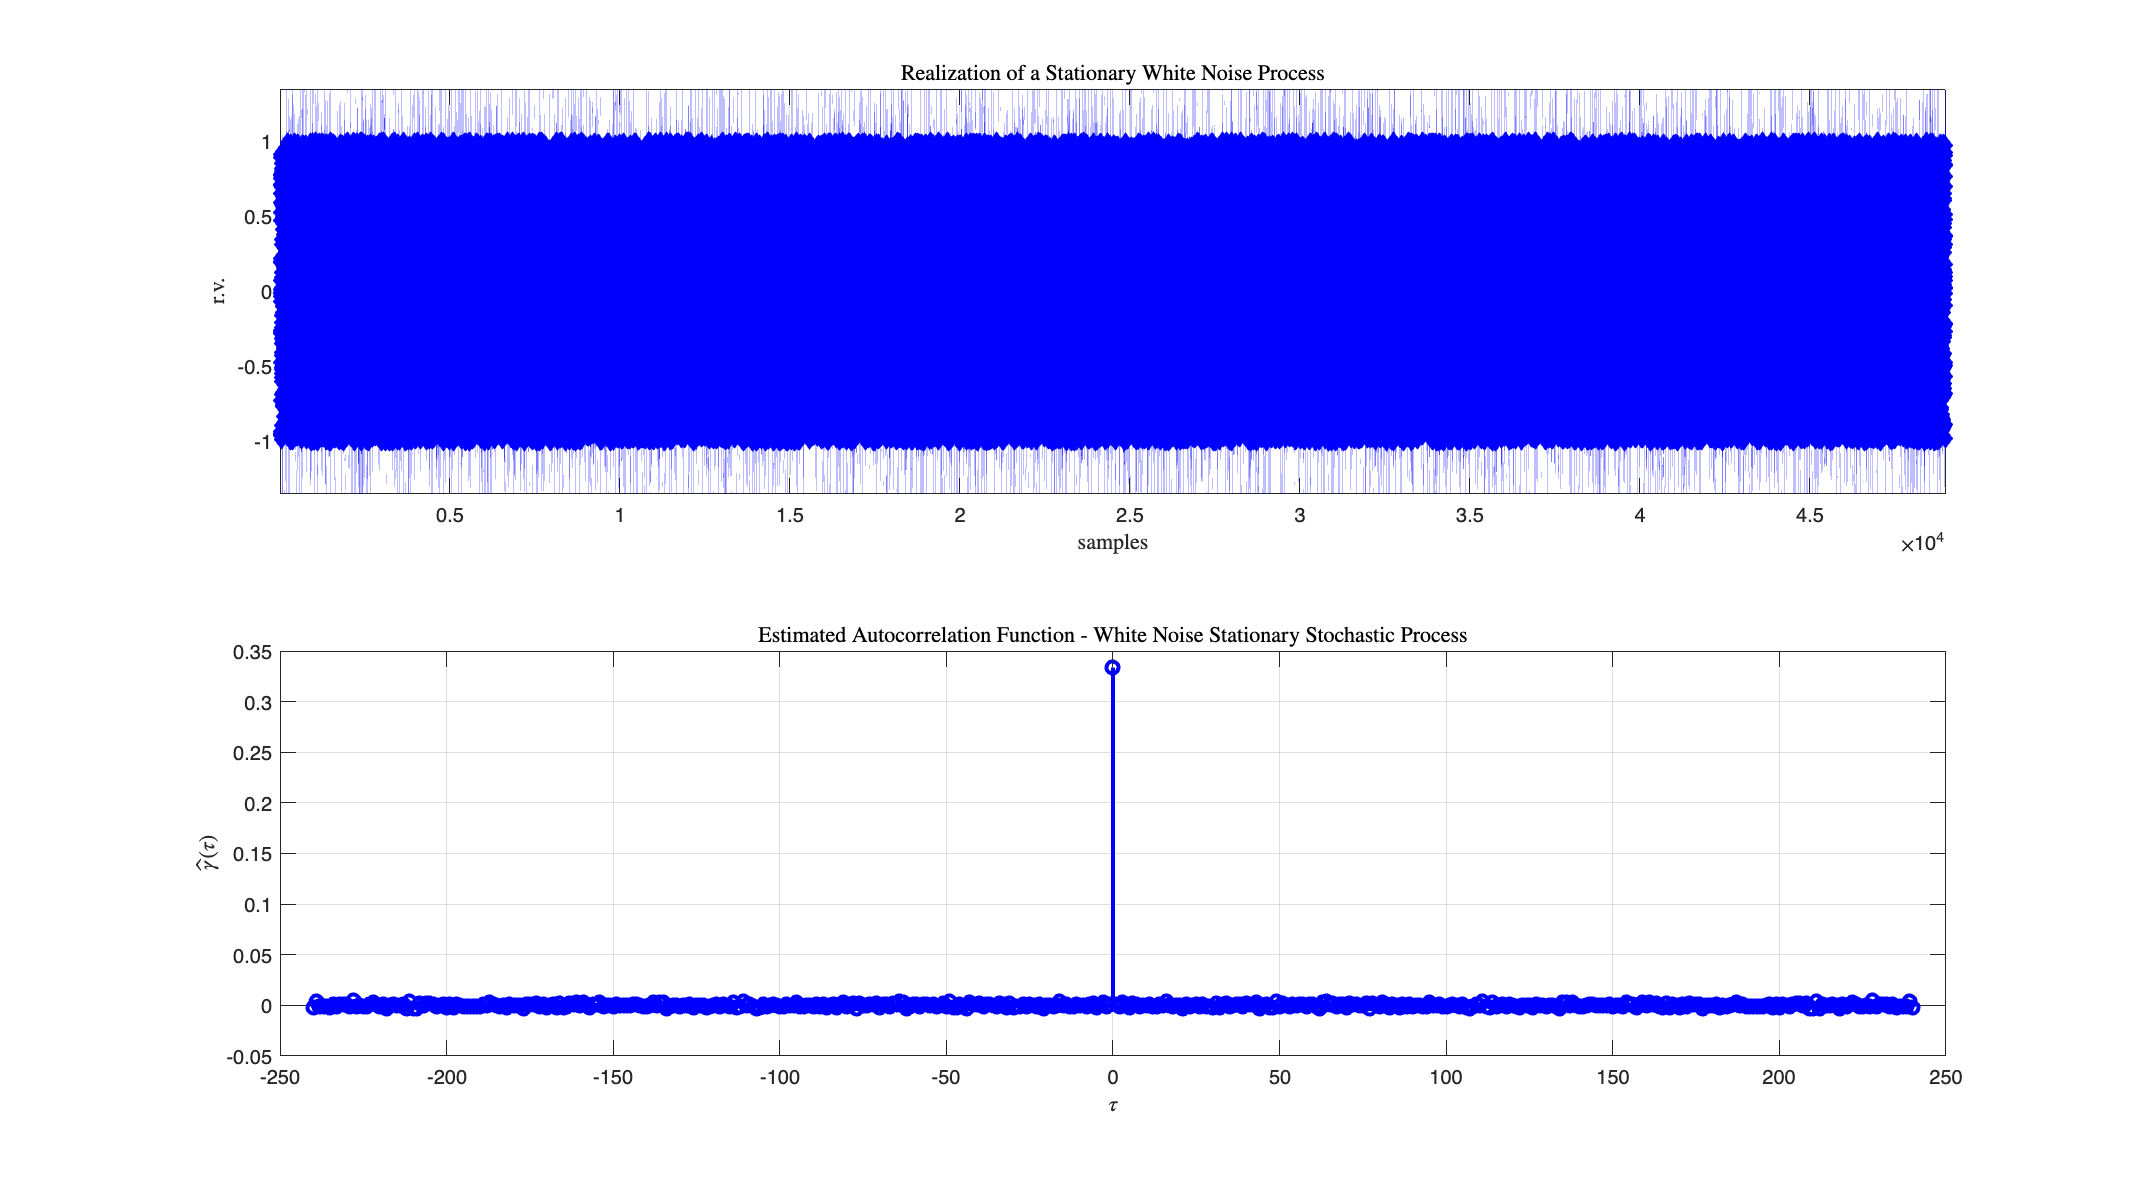

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);
plot(WUsamples,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary White Noise Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis
ylim([-1.35, +1.35]); % and the extrema on the y-axis
grid on

subplot(2,1,2);
stem(lags_v, gamma_vU,'b', 'LineWidth',2);grid on;
xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - White Noise Stationary Stochastic Process',...
    'Interpreter','latex');

#### Estimation of the Spectrum

Given the samples, collected in the `array WUsamples`, let's apply the "periodogram" algorithm to estimate the spectrum:

- Evaluate the DFT of the data sequence

WU_FFTd = fft(WUsamples);   % compute the FFT of the data sequence

WU_FFT = fftshift(WU_FFTd); % rearrange the array of the FFT, by shifting 
                           % the zero-frequency component to the 
                           % center of the array.

- Compute the power spectrum estimate according to Eq. (*)

powerSpectrumU = (abs(WU_FFT).^2)/Ndata; 
% squared magnitude, scaled by the number of samples Nstep
% and scaled also by the 


- Compute the corresponding angular frequencies

omegaPSDU = linspace(-pi,pi,Ndata); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum


- plotting the spectrum

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSDU,powerSpectrumU, 'LineStyle','-','LineWidth',2); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');

#### **Remark**

As written above, the periodogram is an estimate that can be very rough: this is the case. Anyway, if we evaluate the average spectral power density:

% the average spectral power density
averagePSDU = mean(powerSpectrumU)

averagePSDU = 0.3338

As can be seen, the value obtained is close enough to the variance of white noise

varWU

varWU = 0.3333

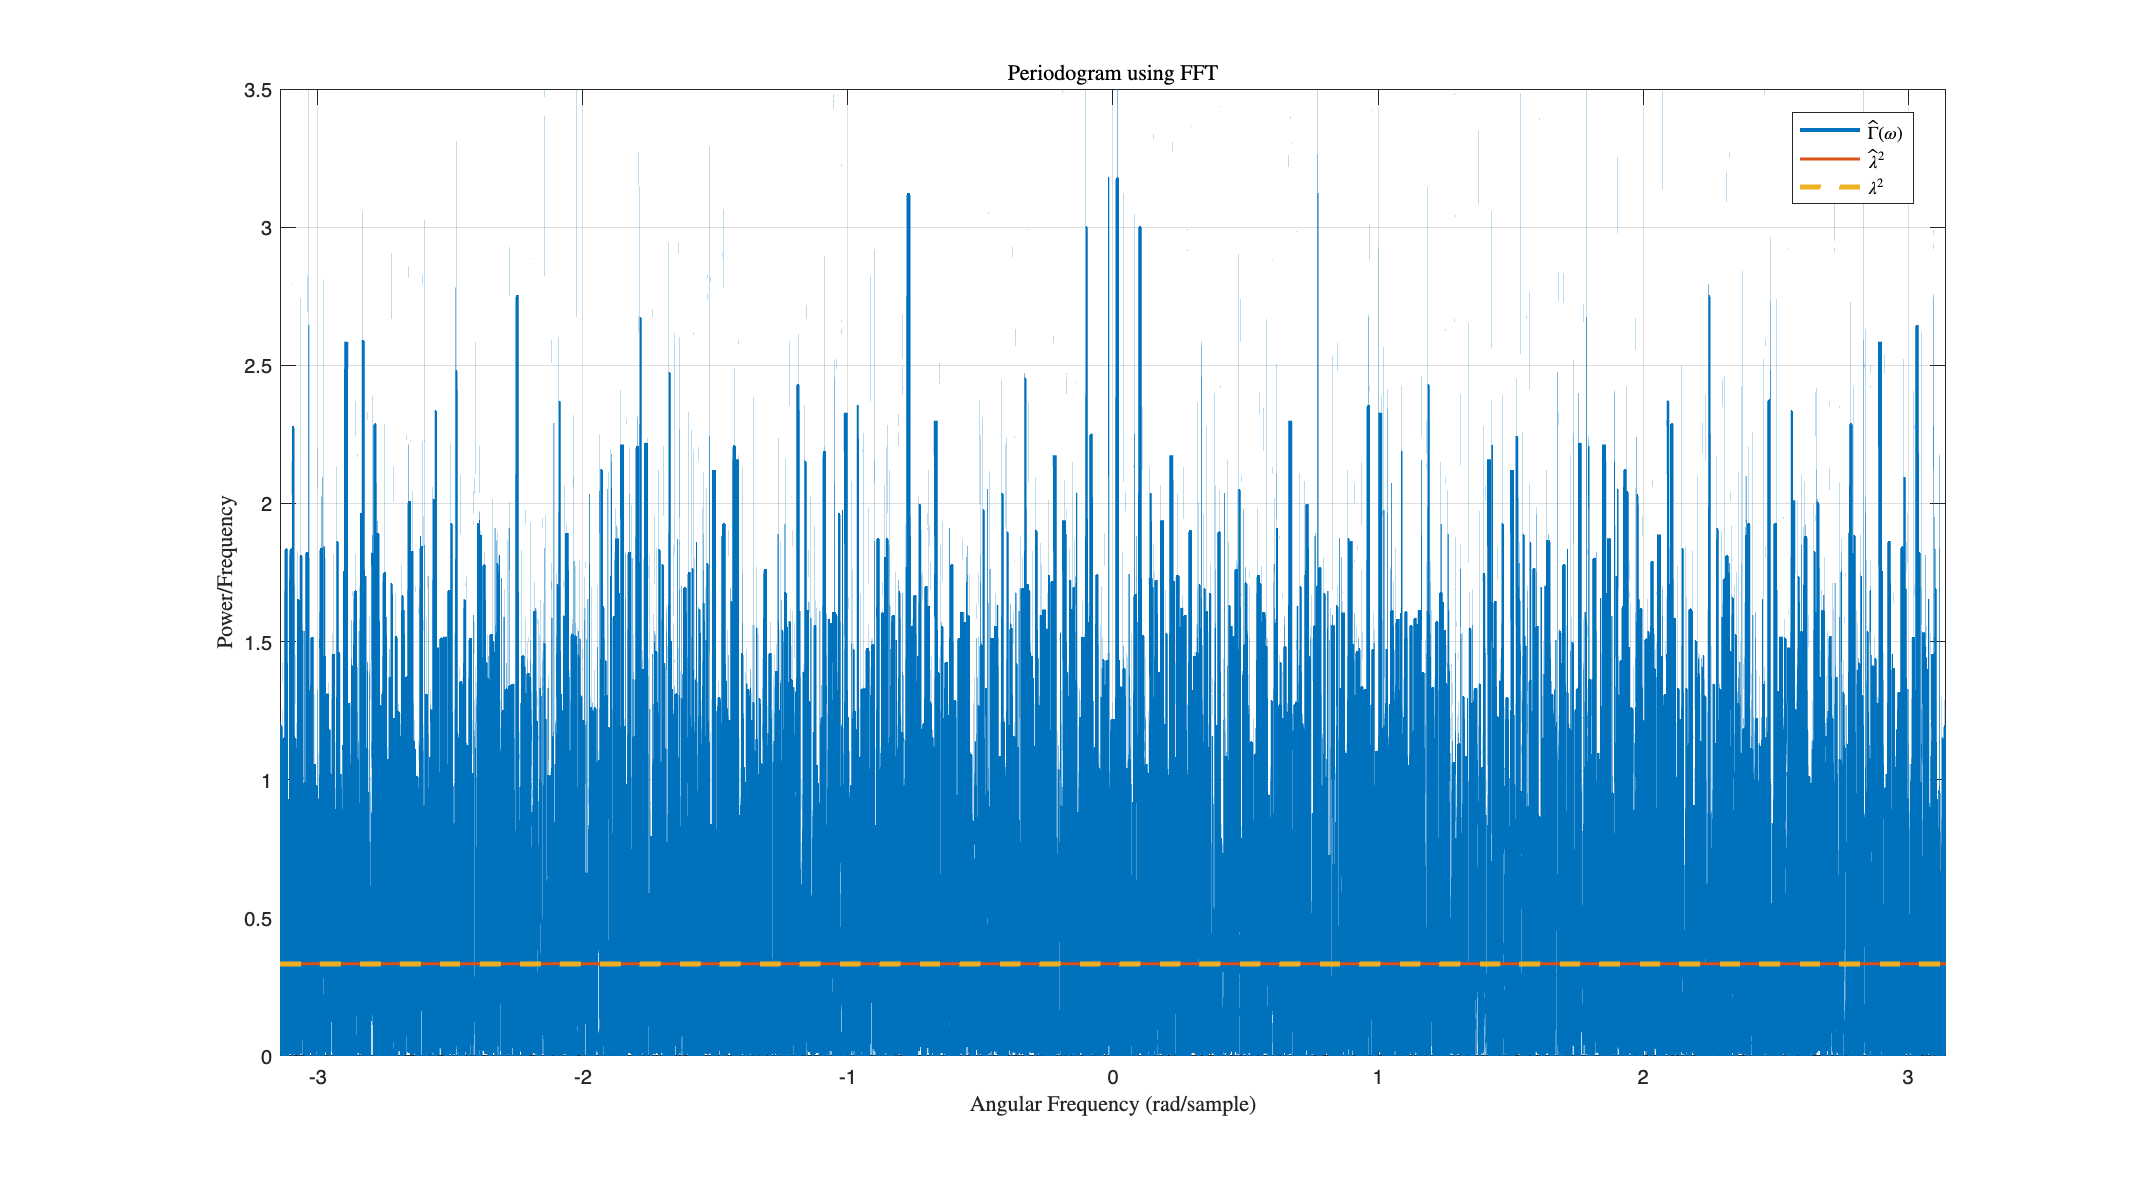



hold on;
omExtrema = [-pi, +pi]; % the min & max angular frequency
plot(omExtrema, [averagePSDU, averagePSDU], 'LineStyle','-', 'LineWidth',1.5);
% a stright line - the average power density

plot(omExtrema, [varWU, varWU], 'LineStyle','--', 'LineWidth',2.5); 
% a stright line - the effective power density

legend('$\hat{\Gamma}(\omega)$','$\hat{\lambda}^{2}$', '$\lambda^2$',...
    'Location','best', 'Interpreter', 'latex');

## References

[1] Proakis, John G. and Manolakis, Dimitris K.  * Digital Signal Processing (3rd Edition),* Prentice Hall,  1996.  